# **FrankaEmikaPanda Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'frankaEmikaPanda';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

% 加载你的机器人模型
robot = loadrobot(robot_name, 'DataFormat', 'column');

% 显示机器人模型的详细信息
showdetails(robot)

--------------------
Robot: (11 bodies)

 Idx                Body Name                 Joint Name                 Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                 ----------                 ----------                ----------------   ----------------
   1              panda_link1               panda_joint1                   revolute                  panda_link0(0)   panda_link2(2)  
   2              panda_link2               panda_joint2                   revolute                  panda_link1(1)   panda_link3(3)  
   3              panda_link3               panda_joint3                   revolute                  panda_link2(2)   panda_link4(4)  
   4              panda_link4               panda_joint4                   revolute                  panda_link3(3)   panda_link5(5)  
   5              panda_link5               panda_joint5                   revolute                  panda_link4(4)   panda_link6(6)  
   6          

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "panda_hand"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.


% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

FrankaEmikaPanda_helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

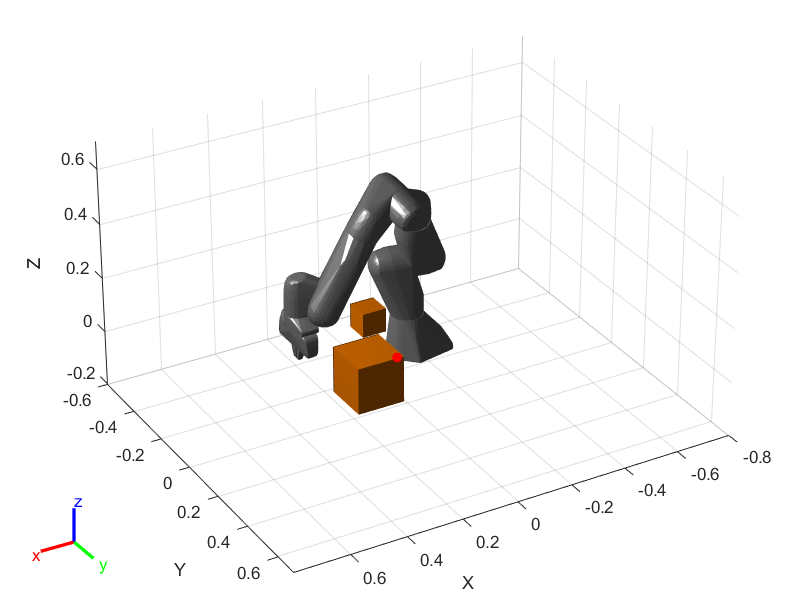

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 2.332364 seconds.


Qtheta = 146.0899

RAR = 2.8064

Elapsed time is 2.198932 seconds.


Qtheta = 142.5765

RAR = 2.8047

Elapsed time is 2.219684 seconds.


Qtheta = 154.0272

RAR = 2.8057

Elapsed time is 2.217383 seconds.


Qtheta = 150.4317

RAR = 2.8041

Elapsed time is 2.244706 seconds.


Qtheta = 140.8146

RAR = 2.8077

Elapsed time is 2.269808 seconds.


Qtheta = 134.7549

RAR = 2.8064

Elapsed time is 2.310744 seconds.


Qtheta = 140.0122

RAR = 2.8091

Elapsed time is 2.251052 seconds.


Qtheta = 129.9589

RAR = 2.8072

Elapsed time is 2.239826 seconds.


Qtheta = 124.2840

RAR = 2.8057

Elapsed time is 2.112456 seconds.


Qtheta = 118.3330

RAR = 2.8061

Elapsed time is 2.170615 seconds.


Qtheta = 115.1467

RAR = 2.8088

Elapsed time is 2.221053 seconds.


Qtheta = 112.9126

RAR = 2.8092

Elapsed time is 2.254136 seconds.


Qtheta = 114.6881

RAR = 2.8111

Elapsed time is 2.215206 seconds.


Qtheta = 113.7249

RAR = 2.8126

Elapsed time is 2.253034 seconds.


Qtheta = 110.4347

RAR = 2.8120

Elapsed time is 2.251712 seconds.


Qtheta = 113.5258

RAR = 2.8134

Elapsed time is 2.276763 seconds.


Qtheta = 107.6268

RAR = 2.8141

Elapsed time is 2.235798 seconds.


Qtheta = 105.2392

RAR = 2.8127

Elapsed time is 2.172835 seconds.


Qtheta = 104.3196

RAR = 2.8133

Elapsed time is 2.096841 seconds.


Qtheta = 101.4375

RAR = 2.8153

Elapsed time is 2.100026 seconds.


Qtheta = 101.0094

RAR = 2.8163

Elapsed time is 2.115626 seconds.


Qtheta = 96.2596

RAR = 2.8167

Elapsed time is 2.194056 seconds.


Qtheta = 91.6991

RAR = 2.8183

Elapsed time is 2.198703 seconds.


Qtheta = 80.8453

RAR = 2.8182

Elapsed time is 2.191501 seconds.


Qtheta = 72.4200

RAR = 2.8189

Elapsed time is 2.205189 seconds.


Qtheta = 73.9971

RAR = 2.8184

Elapsed time is 2.165241 seconds.


Qtheta = 72.5604

RAR = 2.8183

Elapsed time is 2.219075 seconds.


Qtheta = 70.5914

RAR = 2.8196

Elapsed time is 2.189546 seconds.


Qtheta = 62.6996

RAR = 2.8177

Elapsed time is 2.148575 seconds.


Qtheta = 57.8334

RAR = 2.8182

Elapsed time is 2.116891 seconds.


Qtheta = 55.7968

RAR = 2.8190

Elapsed time is 2.454163 seconds.


Qtheta = 54.8413

RAR = 2.8178

Elapsed time is 2.144146 seconds.


Qtheta = 56.7285

RAR = 2.8191

Elapsed time is 2.169203 seconds.


Qtheta = 59.0458

RAR = 2.8232

Elapsed time is 2.142022 seconds.


Qtheta = 58.5578

RAR = 2.8226

Elapsed time is 2.145713 seconds.


Qtheta = 58.9665

RAR = 2.8241

Elapsed time is 2.235099 seconds.


Qtheta = 58.7871

RAR = 2.8259

Elapsed time is 2.346869 seconds.


Qtheta = 55.3530

RAR = 2.8246

Elapsed time is 2.165507 seconds.


Qtheta = 56.4778

RAR = 2.8271

Elapsed time is 2.129491 seconds.


Qtheta = 55.6894

RAR = 2.8286

Elapsed time is 2.174280 seconds.


Qtheta = 50.8209

RAR = 2.8288

Elapsed time is 2.198097 seconds.


Qtheta = 49.9496

RAR = 2.8261

Elapsed time is 2.149983 seconds.


Qtheta = 47.0132

RAR = 2.8256

Elapsed time is 2.195797 seconds.


Qtheta = 46.4182

RAR = 2.8264

Elapsed time is 2.180534 seconds.


Qtheta = 46.5243

RAR = 2.8255

Elapsed time is 2.205372 seconds.


Qtheta = 46.1245

RAR = 2.8248

Elapsed time is 2.229750 seconds.


Qtheta = 41.0780

RAR = 2.8265

Elapsed time is 2.171191 seconds.


Qtheta = 40.4817

RAR = 2.8273

Elapsed time is 2.163856 seconds.


Qtheta = 39.8235

RAR = 2.8285

Elapsed time is 2.170736 seconds.


Qtheta = 41.1996

RAR = 2.8268

Elapsed time is 2.265144 seconds.


Qtheta = 41.7056

RAR = 2.8268

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   1


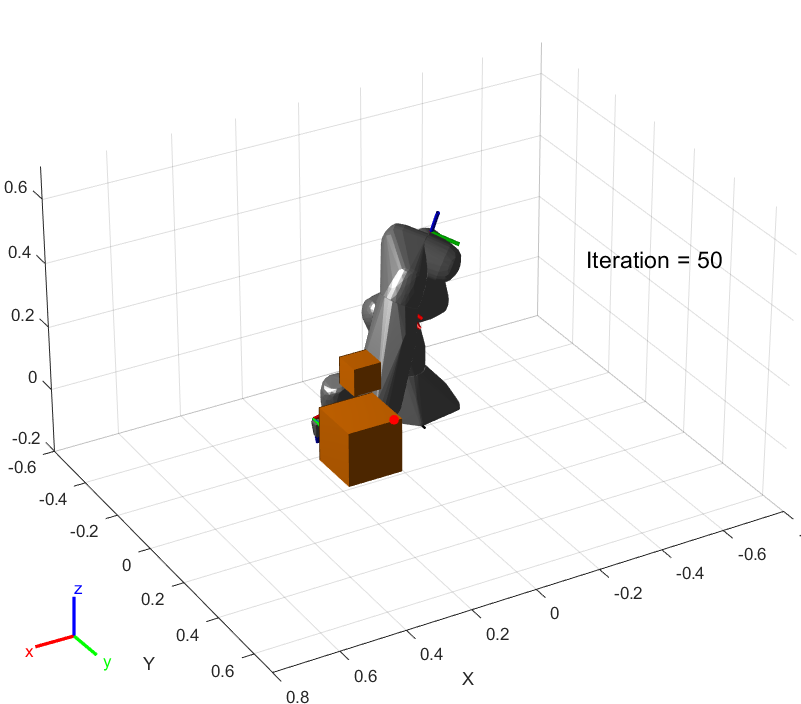

Error using VideoWriter/writeVideo
Frame must be 801 by 600

Error in helperSTOMP (line 165)
        writeVideo(v,frame);

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.